% Data points of ARBCD
feas_all = [];
time_all = [];
iter_all = [];
for intv = 100:200:900
    % Generate distributions
    x = -1:1/intv:1; y = x; n = length(x);
    c = ones(n,1)/n;
    r = pdf('Normal',y,0,1)'; r = r/sum(r);
    X0 = r*c';
    C = zeros(n,n);
    for i = 1:n
        for j = 1:n
            C(i,j) = (y(i)-x(j))^2;
        end
    end
    % Inverse function method
    X_opt = zeros(n,n);
    j=1;
    i=1;
    resid_j=1/n;
    r0=r;
    while (i<=n&&j<=n)
        if resid_j>=r0(i)
            X_opt(i,j)=X_opt(i,j)+r0(i);
            resid_j=resid_j-r0(i);
            r0(i)=0;
            i=i+1;
        else
            X_opt(i,j)=X_opt(i,j)+resid_j;
            j=j+1;
            r0(i)=r0(i)-resid_j;
            resid_j=1/n;
        end
    end
    f_opt = trace(C'*X_opt);
    % Accelerated RBCD
    maxiter = 10000;
    M = 100;
    [time,iter,feas] = ARBCD1(r,c,n,X0,f_opt,C,M,maxiter,1,1e-4);
    time_all = [time_all,time];
    iter_all = [iter_all,iter];
    feas_all = [feas_all,feas];
end

number of successful iterations =32
number of successful iterations =38
number of successful iterations =36
number of successful iterations =36
number of successful iterations =35
number of successful iterations =365


% Data points for Sinkhorn
sink_feas_all = [];
sink_time_all = [];
sink_iter_all = [];
for intv = 100:200:900
    % Generate distributions
    x = -1:1/intv:1; y = x; n = length(x);
    c = ones(n,1)/n;
    r = pdf('Normal',y,0,1)'; r = r/sum(r);
    X0 = r*c';
    C = zeros(n,n);
    for i = 1:n
        for j = 1:n
            C(i,j) = (y(i)-x(j))^2;
        end
    end
    % Inverse function method
    X_opt = zeros(n,n);
    j=1;
    i=1;
    resid_j=1/n;
    r0=r;
    while (i<=n&&j<=n)
        if resid_j>=r0(i)
            X_opt(i,j)=X_opt(i,j)+r0(i);
            resid_j=resid_j-r0(i);
            r0(i)=0;
            i=i+1;
        else
            X_opt(i,j)=X_opt(i,j)+resid_j;
            j=j+1;
            r0(i)=r0(i)-resid_j;
            resid_j=1/n;
        end
    end
    f_opt = trace(C'*X_opt);
    % Sinkhorn
    maxiter = 300000;
    [iter_sink,time_sink,feas_sink,X1] = Sinkhorn1(r,c,1e-3,C,f_opt,maxiter,1e-4);
    sink_time_all = [sink_time_all,time_sink];
    sink_iter_all = [sink_iter_all,iter_sink];
    sink_feas_all = [sink_feas_all,feas_sink];
end

k = 1000, accuracy = 0.041698
k = 2000, accuracy = 0.036638
k = 3000, accuracy = 0.031776
k = 4000, accuracy = 0.028082
k = 5000, accuracy = 0.024503
k = 6000, accuracy = 0.021868
k = 7000, accuracy = 0.019191
k = 8000, accuracy = 0.016897
k = 9000, accuracy = 0.015127
k = 10000, accuracy = 0.013435


number of successful iterations =27
number of successful iterations =29
number of successful iterations =27
number of successful iterations =28
number of successful iterations =31


k = 1000, accuracy = 0.042446
k = 2000, accuracy = 0.037711
k = 3000, accuracy = 0.033648
k = 4000, accuracy = 0.030125
k = 5000, accuracy = 0.027044
k = 6000, accuracy = 0.024326
k = 7000, accuracy = 0.021916
k = 8000, accuracy = 0.019767
k = 9000, accuracy = 0.017844
k = 10000, accuracy = 0.01612


number of successful iterations =257
number of successful iterations =298
number of successful iterations =242
number of successful iterations =319
number of successful iterations =272


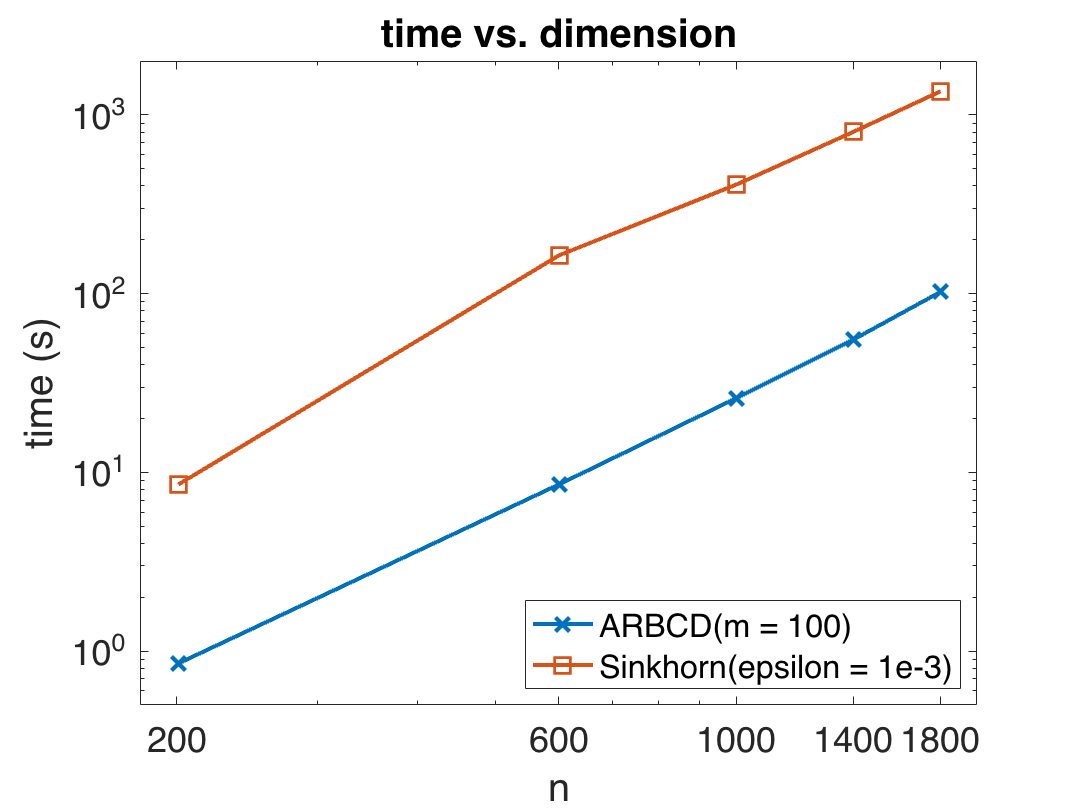

% Plot
naxis = 201:400:1801;
figure
loglog(naxis,time_all1,'-x','LineWidth',2,MarkerSize=10);
hold on
loglog(naxis,sink_time_all,'-s','LineWidth',2,MarkerSize=10);
xlim([180 2e3])
xticks([200,600,1000,1400,1800])
ylim([0.5 2e3])
legend('ARBCD(m = 100)','Sinkhorn(epsilon = 1e-3)','location','southeast')
title('time vs. dimension')
xlabel('n')
ylabel('time (s)')
set(gca,'FontSize',18)